# **Assignment 1 COT-5930 Digital Image Processing**

## **Read & Display Image**

**       Part  A. Read an image into a workspace variable (select from drop down).**

**        Part B. Display the image.**

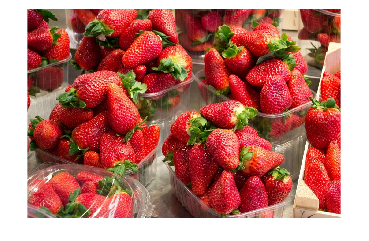


% change directory folder to pick images from
path= 'C:\Users\shukl\Documents\GitHub\COT5930-Image-Processing\Assignment1\Input_Images\';
cd (path)
file_names = dir('**/');
file_names = file_names(~[file_names.isdir]);
file_names = string({file_names.name})';

% select Image from using drop down
Select_an_Image = file_names(5);

% Read and display the image
Input_Image=strcat(path,Selected_Image);
A=imread(Input_Image);
imshow(A)

## **Apply Effects and Display Results**

**        Part C. Apply an image processing filter/effect of your choice to the image (select an effect from drop down).**

**        Part D. Display the result.**

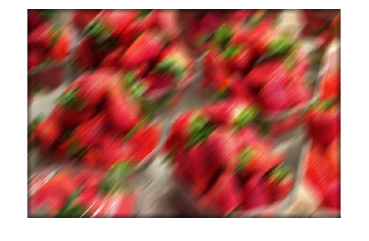

% parameter for blur filter
h = fspecial('motion', 50, 45);

% select effect to be performed on image
Select_an_effect = "imfilter(A,h)";

% apply the effect and show the new image
B=eval(effects);
imshow(B)

## Save the Output

**         Part E. Save the resulting image to a  desired format file.**

% select the desired format for saving the new image
Saving_File_format = ".jpg";

% Create new file name
[~,name,~] = fileparts(Selected_Image);
newfile=strcat(name,'_new',save_format);

%change directory to location where image has to be saved
cd 'C:\Users\shukl\Documents\GitHub\COT5930-Image-Processing\Assignment1\Output_Images\'

% save image in desired format
imwrite(B,newfile)


## **Refrences**

    1). [https://www.mathworks.com/videos/how-to-use-live-editor-controls-1569868241587.html](https://www.mathworks.com/videos/how-to-use-live-editor-controls-1569868241587.html)

    2). [https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html)

    3). [https://www.mathworks.com/videos/how-to-turn-your-script-into-a-simple-app-1653572686561.html](https://www.mathworks.com/videos/how-to-turn-your-script-into-a-simple-app-1653572686561.html)